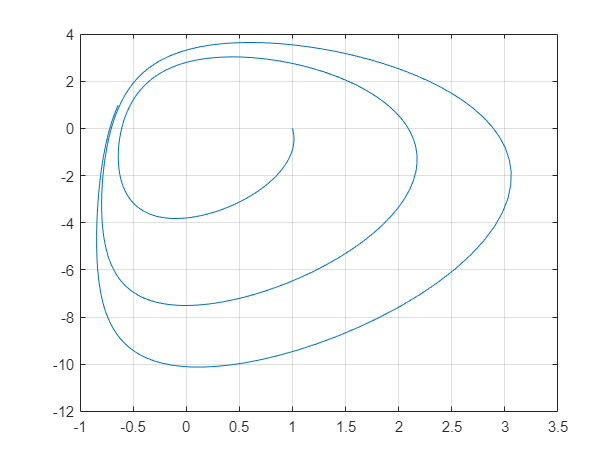

% Runge-Kutta 4 implementations
% First implementation using functions dxdt and dydt.

% time period
ts=0; te=5;
% time step
h = 0.01;
% number of points
N = round((te-ts)/h);

% initialise vectors
x=zeros(N,1); y=zeros(N,1);
% initial conditions
x(1)=1; y(1)=0;

% ODE system
a1=1;b1=1;c1=0;al1=0;bt1=1;
a2=-10;b2=2.2;c2=0.7;al2=-72-7/9;bt2=0.0015;
dxdt=@(x,y) a1*x^2 + b1*x*y + c1*y^2 + al1*x + bt1*y;
dydt=@(x,y) a2*x^2 + b2*x*y + c2*y^2 + al2*x + bt2*y;

for i=1:N

    k1x=dxdt(x(i), y(i));
    k1y=dydt(x(i), y(i));
    
    k2x=dxdt(x(i)+h/2*k1x, y(i)+h/2*k1y);
    k2y=dxdt(x(i)+h/2*k1x, y(i)+h/2*k1y);
    
    k3x=dxdt(x(i)+h/2*k2x, y(i)+h/2*k2y);
    k3y=dxdt(x(i)+h/2*k2x, y(i)+h/2*k2y);
    
    k4x=dxdt(x(i)+h*k3x, y(i)+h*k3y);
    k4y=dxdt(x(i)+h*k3x, y(i)+h*k3y);
    
    x(i+1)=x(i) + h/6*(k1x+2*k2x+2*k3x+k4x);
    y(i+1)=y(i) + h/6*(k1y+2*k2y+2*k3y+k4y);

end

plot(x,y); grid on

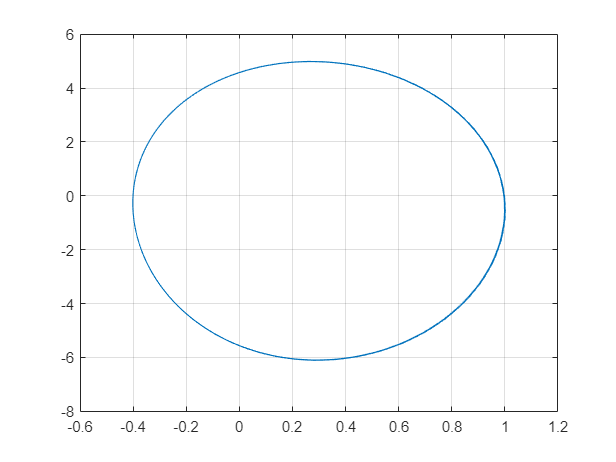

% Second implementation using function odefun.

% time period
ts=0; te=5;
% time step
h = 0.01;
% number of points
N = round((te-ts)/h);

% initialise vectors
x=zeros(N,1); y=zeros(N,1);
% initial conditions
x(1)=1; y(1)=0;

for i=1:N

    k1=odefun([x(i), y(i)]);

    k2=odefun([x(i)+h/2*k1(1), y(i)+h/2*k1(2)]);
    
    k3=odefun([x(i)+h/2*k2(1), y(i)+h/2*k2(2)]);
    
    k4=odefun([x(i)+h*k3(1), y(i)+h*k3(2)]);
    
    x(i+1)=x(i) + h/6*(k1(1)+2*k2(1)+2*k3(1)+k4(1));
    y(i+1)=y(i) + h/6*(k1(2)+2*k2(2)+2*k3(2)+k4(2));
            
end

plot(x,y); grid on

function dz=odefun(z)
    a1=1;b1=1;c1=0;al1=0;bt1=1;
    a2=-10;b2=2.2;c2=0.7;al2=-72-7/9;bt2=0.0015;
    dz=zeros(2,1); % z=(z(1),z(2))=(x,y)
    
    dz(1)=(a1*z(1)^2 + b1*z(1)*z(2) + c1*z(2)^2 + al1*z(1) + bt1*z(2));
    dz(2)=(a2*z(1)^2 + b2*z(1)*z(2) + c2*z(2)^2 + al2*z(1) + bt2*z(2));
end